# EJERCICIO 3

## LOAD

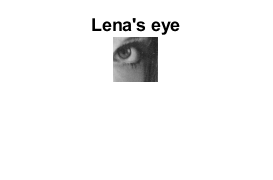

load lena512.mat
lenarec = lena512(252:296,318:362);% Crop the image to a 45 x 45 vector
figure(1);
imshow(uint8(lenarec))
title("Lena's eye");

b = de2bi(lenarec,8,'left-msb'); % Convert the samples from uint8 to binary
b = b';     
bits = b(:);


ford=100;     % Orden del Filtro 
f=   [0 0.3045 0.3045 1];  % Vector de Frecuencias
m= [1 1 0 0]; % Vector de Magnitudes 
f1 = fir2(ford,f,m);  % Coeficientes del Filtro usando FIR2( ) 
%%fvtool(f2)    
f=   [0 0.1545 0.1545 1];  % Vector de Frecuencias 
f2 = fir2(ford,f,m);  % Coeficientes del Filtro usando FIR2( ) 
%%fvtool(f1)          % Herramienta para analizar el Filtro 
f=   [0 0.045 0.045 1];  % Vector de Frecuencias
f3 = fir2(ford,f,m);     % Coeficientes del Filtro usando FIR2( ) 
%%fvtool(f2)    

## UNRZ




Fs= 96000;
mp= 10;
%No_bits= 8712;
Baud_rate= Fs/mp   %Symbols per second

Baud_rate = 9600

Bit_rate=Baud_rate % bits/s

Bit_rate = 9600

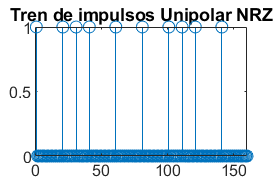

Ts=1/Fs;
% The bit rate is Rb= Rs= Fs / mp, because 1 bit= 1 symbol and  every symbol has mp
% samples per bit

%pnrz = [1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1]; % Pulse type with mp samples
pnrz =ones(1,mp); % Similar to Arduino pulses with 5V----PBase
%wvtool(pnrz)

s = zeros(1,numel(bits)*mp);
s(1:mp:end) = bits;  % Impulse Train
stem(s(1:mp*16))
title('Tren de impulsos Unipolar NRZ');

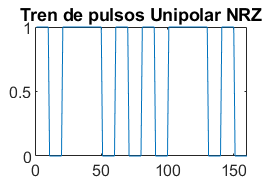

xUNRZ = conv(pnrz,s); % Pulse Train
plot(xUNRZ(1:mp*16))
title('Tren de pulsos Unipolar NRZ');

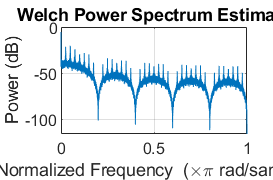

pwelch(xUNRZ,[],[],[],'power'); % PSD of Unipolar NRZ

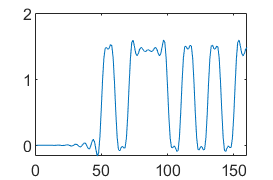

%%wvtool(xUNRZ)

pow = sum(xUNRZ.^2)/numel(xUNRZ);
pow_Deseada = 1;
xUNRZ = sqrt(pow_Deseada/pow)*xUNRZ;

xUNRZ_filtrado_f1 = conv(xUNRZ,f1);
xUNRZ_filtrado_f2 = conv(xUNRZ,f2);
xUNRZ_filtrado_f3 = conv(xUNRZ,f3);

%c)
plot(xUNRZ_filtrado_f1(1:mp*16));

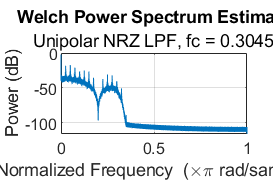

pwelch(xUNRZ_filtrado_f1,[],[],[],'power'); % PSD 
subtitle("Unipolar NRZ LPF, fc = 0.3045"); 

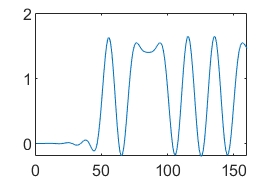

plot(xUNRZ_filtrado_f2(1:mp*16));

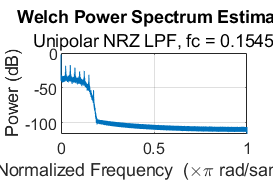

pwelch(xUNRZ_filtrado_f2,[],[],[],'power'); % PSD 
subtitle("Unipolar NRZ LPF, fc = 0.1545"); 

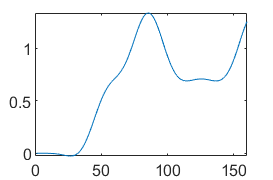

plot(xUNRZ_filtrado_f3(1:mp*16));

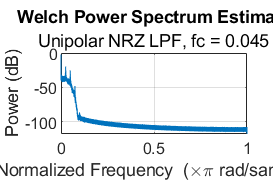

pwelch(xUNRZ_filtrado_f3,[],[],[],'power'); % PSD 
subtitle("Unipolar NRZ LPF, fc = 0.045"); 

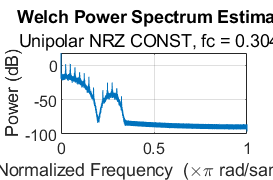


Match_filter1 = fliplr(pnrz);

Const1 =conv(Match_filter1,xUNRZ_filtrado_f1);
Const2 =conv(Match_filter1,xUNRZ_filtrado_f2);
Const3 =conv(Match_filter1,xUNRZ_filtrado_f3);

pwelch(Const1,[],[],[],'power'); % PSD 
subtitle("Unipolar NRZ CONST, fc = 0.3045"); 

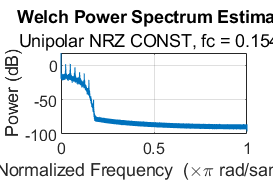

pwelch(Const2,[],[],[],'power'); % PSD 
subtitle("Unipolar NRZ CONST, fc = 0.1545"); 

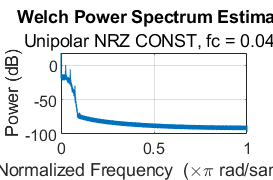

pwelch(Const3,[],[],[],'power'); % PSD 
subtitle("Unipolar NRZ CONST, fc = 0.045"); 



% 1.e) recover the transmitted bits
% UNRZ
bits2send = bits';
bits_RX_UNRZ_1 = zeros(1,numel(bits2send));
bits_RX_UNRZ_2 = zeros(1,numel(bits2send));
bits_RX_UNRZ_3 = zeros(1,numel(bits2send));

start = (ford/2) + (mp/2) + (mp/2) ; % Take to account the delay produced by the filter
xUNRZ_f_m1 = Const1(start:mp:end);
xUNRZ_f_m2 = Const2(start:mp:end);
xUNRZ_f_m3 = Const3(start:mp:end);

bits_RX_UNRZ_1(xUNRZ_f_m1 > (max(Const1)/2)) = 1;   %Umbral +
bits_RX_UNRZ_2(xUNRZ_f_m2 > (max(Const2)/2)) = 1;   %Umbral +
bits_RX_UNRZ_3(xUNRZ_f_m3 > (max(Const3)/2)) = 1;   %Umbral +

xUNRZ_BER_1 = (sum(xor(bits2send,bits_RX_UNRZ_1))/numel(bits2send)) * 100

xUNRZ_BER_1 = 0

xUNRZ_BER_2 = (sum(xor(bits2send,bits_RX_UNRZ_2))/numel(bits2send)) * 100

xUNRZ_BER_2 = 0

xUNRZ_BER_3 = (sum(xor(bits2send,bits_RX_UNRZ_3))/numel(bits2send)) * 100

xUNRZ_BER_3 = 23.2593

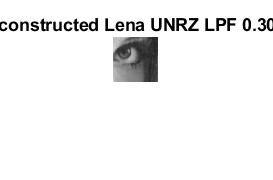



bitsM1 = reshape(bits_RX_UNRZ_1,8,45*45);
bitsM1 = bitsM1';
decval1 = bi2de(bitsM1,'left-msb');
lenaRS1 = reshape(decval1, size(lenarec));
imshow(uint8(lenaRS1))
title("Reconstructed Lena UNRZ LPF 0.3045");

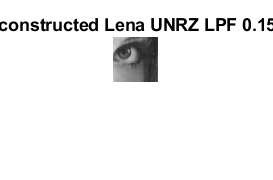


bitsM2 = reshape(bits_RX_UNRZ_2,8,45*45);
bitsM2 = bitsM2';
decval2 = bi2de(bitsM2,'left-msb');
lenaRS2 = reshape(decval2, size(lenarec));
imshow(uint8(lenaRS2))
title("Reconstructed Lena UNRZ LPF 0.1545");

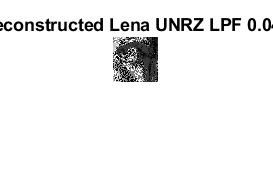


bitsM3 = reshape(bits_RX_UNRZ_3,8,45*45);
bitsM3 = bitsM3';
decval3 = bi2de(bitsM3,'left-msb');
lenaRS3 = reshape(decval3, size(lenarec));
imshow(uint8(lenaRS3))
title("Reconstructed Lena UNRZ LPF 0.045");

## PNRZ

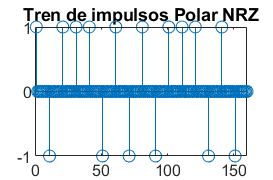


pnrz=ones(1,mp);
s1=bits;
s1(s1==0)=-1;
s=zeros(1,numel(s1)*mp);
s(1:mp:end)=s1; %Impulse train
stem(s(1:mp*16))
title('Tren de impulsos Polar NRZ');

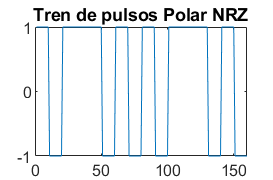

xPNRZ=conv(pnrz,s); %Pulse train
plot(xPNRZ(1:mp*16))
title('Tren de pulsos Polar NRZ');

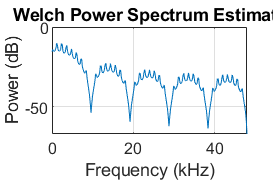

pwelch(xPNRZ,500,300,500,Fs,'power');

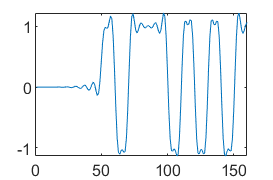


pow = sum(xPNRZ.^2)/numel(xPNRZ);
pow_Deseada = 1;
xPNRZ = sqrt(pow_Deseada/pow)*xPNRZ;

xPNRZ_filtrado_f1 = conv(xPNRZ,f1);
xPNRZ_filtrado_f2 = conv(xPNRZ,f2);
xPNRZ_filtrado_f3 = conv(xPNRZ,f3);

%c)
plot(xPNRZ_filtrado_f1(1:mp*16));

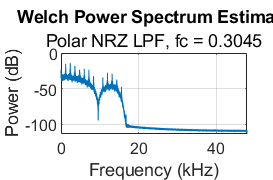

pwelch(xPNRZ_filtrado_f1,[],[],[],Fs,'power'); % PSD 
subtitle("Polar NRZ LPF, fc = 0.3045"); 

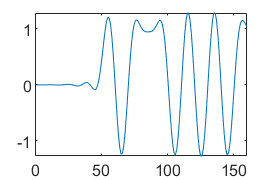

plot(xPNRZ_filtrado_f2(1:mp*16));

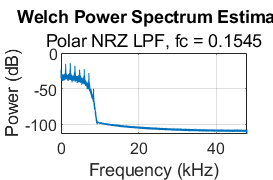

pwelch(xPNRZ_filtrado_f2,[],[],[],Fs,'power'); % PSD 
subtitle("Polar NRZ LPF, fc = 0.1545"); 

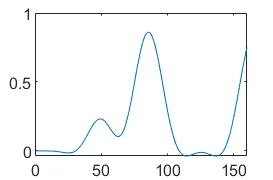

plot(xPNRZ_filtrado_f3(1:mp*16));

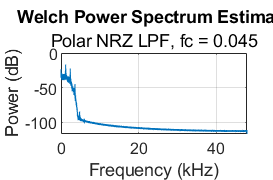

pwelch(xPNRZ_filtrado_f3,[],[],[],Fs,'power'); % PSD 
subtitle("Polar NRZ LPF, fc = 0.045"); 

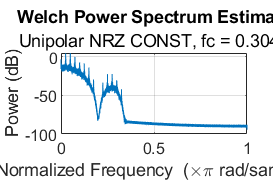

%match filter
Match_filter2 = fliplr(pnrz);

Const11 =conv(Match_filter2,xPNRZ_filtrado_f1);
Const22 =conv(Match_filter2,xPNRZ_filtrado_f2);
Const33 =conv(Match_filter2,xPNRZ_filtrado_f3);

pwelch(Const11,[],[],[],'power'); % PSD 
subtitle("Unipolar NRZ CONST, fc = 0.3045"); 

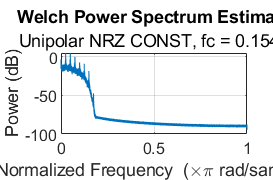

pwelch(Const22,[],[],[],'power'); % PSD 
subtitle("Unipolar NRZ CONST, fc = 0.1545"); 

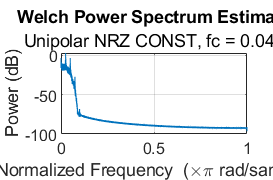

pwelch(Const33,[],[],[],'power'); % PSD 
subtitle("Unipolar NRZ CONST, fc = 0.045"); 


bits_RX_PNRZ_1 = zeros(1,numel(bits2send));
bits_RX_PNRZ_2 = zeros(1,numel(bits2send));
bits_RX_PNRZ_3 = zeros(1,numel(bits2send));

start = (ford/2) + (mp/2) + (mp/2); % Take to account the delay produced by the filter
xPNRZ_f_m1 = Const11(start:mp:end);
xPNRZ_f_m2 = Const22(start:mp:end);
xPNRZ_f_m3 = Const33(start:mp:end);

bits_RX_PNRZ_1(xPNRZ_f_m1 > (max(Const11)/2)) = 1;   %Umbral +
bits_RX_PNRZ_2(xPNRZ_f_m2 > (max(Const22)/2)) = 1;   %Umbral +
bits_RX_PNRZ_3(xPNRZ_f_m3 > (max(Const33)/2)) = 1;   %Umbral +

xPNRZ_BER_1 = (sum(xor(bits2send,bits_RX_PNRZ_1))/numel(bits2send)) * 100

xPNRZ_BER_1 = 0

xPNRZ_BER_2 = (sum(xor(bits2send,bits_RX_PNRZ_2))/numel(bits2send)) * 100

xPNRZ_BER_2 = 0

xPNRZ_BER_3 = (sum(xor(bits2send,bits_RX_PNRZ_3))/numel(bits2send)) * 100

xPNRZ_BER_3 = 38.3765

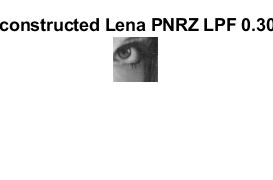


bitsM1 = reshape(bits_RX_PNRZ_1,8,45*45);
bitsM1 = bitsM1';
decval1 = bi2de(bitsM1,'left-msb');
lenaRS1 = reshape(decval1, size(lenarec));
imshow(uint8(lenaRS1))
title("Reconstructed Lena PNRZ LPF 0.3045");

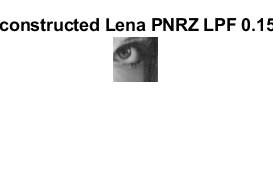


bitsM2 = reshape(bits_RX_PNRZ_2,8,45*45);
bitsM2 = bitsM2';
decval2 = bi2de(bitsM2,'left-msb');
lenaRS2 = reshape(decval2, size(lenarec));
imshow(uint8(lenaRS2))
title("Reconstructed Lena PNRZ LPF 0.1545");

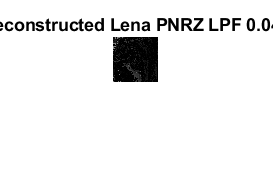


bitsM3 = reshape(bits_RX_PNRZ_3,8,45*45);
bitsM3 = bitsM3';
decval3 = bi2de(bitsM3,'left-msb');
lenaRS3 = reshape(decval3, size(lenarec));
imshow(uint8(lenaRS3))
title("Reconstructed Lena PNRZ LPF 0.045");

## MANCHESTER

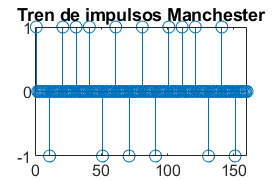


pm=[ones(1,mp/2),-1*ones(1,mp/2)]; 
s1=bits;
s1(s1==0)=-1;
s=zeros(1,numel(bits)*mp);
s(1:mp:end)=s1;
stem(s(1:mp*16))
title('Tren de impulsos Manchester');

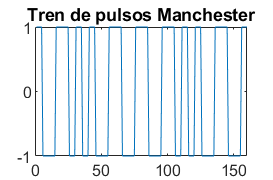

xMANCH=conv(pm,s);
plot(xMANCH(1:mp*16));  % Show 16 symbols
title('Tren de pulsos Manchester');

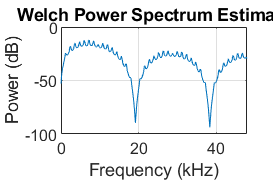

pwelch(xMANCH,500,300,500,Fs,'power');

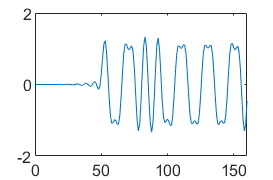


pow = sum(xMANCH.^2)/numel(xMANCH);
pow_Deseada = 1;
xMANCH = sqrt(pow_Deseada/pow)*xMANCH;

xMANCH_filtrado_f1 = conv(xMANCH,f1);
xMANCH_filtrado_f2 = conv(xMANCH,f2);
xMANCH_filtrado_f3 = conv(xMANCH,f3);

%c)
plot(xMANCH_filtrado_f1(1:mp*16));

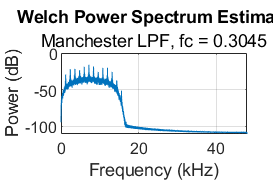

pwelch(xMANCH_filtrado_f1,[],[],[],Fs,'power'); % PSD 
subtitle("Manchester LPF, fc = 0.3045"); 

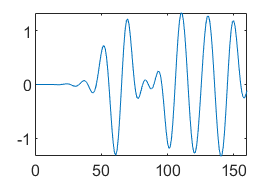

plot(xMANCH_filtrado_f2(1:mp*16));

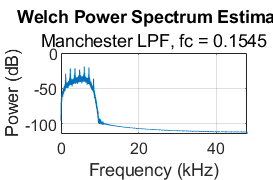

pwelch(xMANCH_filtrado_f2,[],[],[],Fs,'power'); % PSD 
subtitle("Manchester LPF, fc = 0.1545"); 

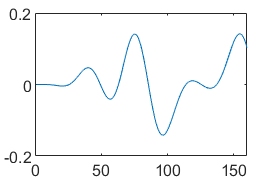

plot(xMANCH_filtrado_f3(1:mp*16));

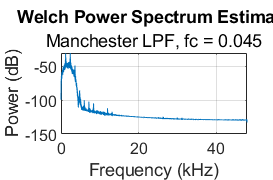

pwelch(xMANCH_filtrado_f3,[],[],[],Fs,'power'); % PSD 
subtitle("Manchester LPF, fc = 0.045"); 

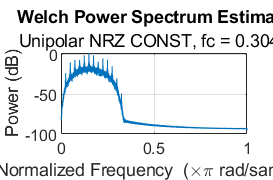



%match filter
Match_filter3 = fliplr(pm);

Const111 =conv(Match_filter3,xMANCH_filtrado_f1);
Const222 =conv(Match_filter3,xMANCH_filtrado_f2);
Const333 =conv(Match_filter3,xMANCH_filtrado_f3);

pwelch(Const111,[],[],[],'power'); % PSD 
subtitle("Unipolar NRZ CONST, fc = 0.3045"); 

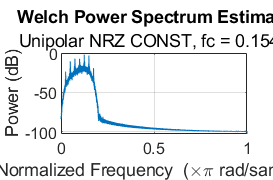

pwelch(Const222,[],[],[],'power'); % PSD 
subtitle("Unipolar NRZ CONST, fc = 0.1545"); 

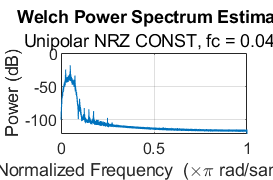

pwelch(Const333,[],[],[],'power'); % PSD 
subtitle("Unipolar NRZ CONST, fc = 0.045"); 


%start = (ford/2) + (mp/2); % Take to account the delay produced by the filter
start = ford/2 + round(mp/4);
start2 = ford/2 + round(mp/2);

x1MAN_f_m1 = Const111(start:mp:end);
x1MAN_f_m2 = Const222(start:mp:end);
x1MAN_f_m3 = Const333(start:mp:end);

x2MAN_f_m1 = Const111(start2:mp:end);
x2MAN_f_m2 = Const222(start2:mp:end);
x2MAN_f_m3 = Const333(start2:mp:end);

xMAN_f_m1 = sign(x2MAN_f_m1 - x1MAN_f_m1); %Sign
xMAN_f_m2 = sign(x2MAN_f_m2 - x1MAN_f_m2); %Sign
xMAN_f_m3 = sign(x2MAN_f_m3 - x1MAN_f_m3); %Sign


bits_RX_MAN_1 = (xMAN_f_m1+1)/2;
bits_RX_MAN_2 = (xMAN_f_m2+1)/2;
bits_RX_MAN_3 = (xMAN_f_m3+1)/2;

bits_RX_MAN_1 = bits_RX_MAN_1(1:numel(bits2send));
bits_RX_MAN_2 = bits_RX_MAN_2(1:numel(bits2send));
bits_RX_MAN_3 = bits_RX_MAN_3(1:numel(bits2send));


xMAN_BER_1 = (sum(xor(bits2send,bits_RX_MAN_1))/numel(bits2send)) * 100

xMAN_BER_1 = 47.3519

xMAN_BER_2 = (sum(xor(bits2send,bits_RX_MAN_2))/numel(bits2send)) * 100

xMAN_BER_2 = 37.4074

xMAN_BER_3 = (sum(xor(bits2send,bits_RX_MAN_3))/numel(bits2send)) * 100

xMAN_BER_3 = 22.9136

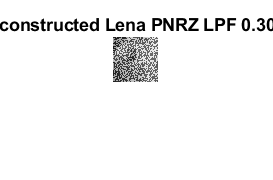


bitsM1 = reshape(bits_RX_MAN_1,8,45*45);
bitsM1 = bitsM1';
decval1 = bi2de(bitsM1,'left-msb');
lenaRS1 = reshape(decval1, size(lenarec));
imshow(uint8(lenaRS1))
title("Reconstructed Lena MANCH LPF 0.3045");

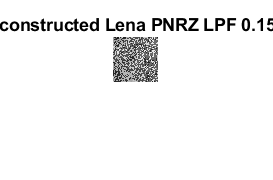


bitsM2 = reshape(bits_RX_MAN_2,8,45*45);
bitsM2 = bitsM2';
decval2 = bi2de(bitsM2,'left-msb');
lenaRS2 = reshape(decval2, size(lenarec));
imshow(uint8(lenaRS2))
title("Reconstructed Lena MANCH LPF 0.1545");

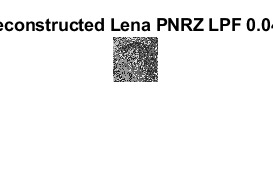


bitsM3 = reshape(bits_RX_MAN_3,8,45*45);
bitsM3 = bitsM3';
decval3 = bi2de(bitsM3,'left-msb');
lenaRS3 = reshape(decval3, size(lenarec));
imshow(uint8(lenaRS3))
title("Reconstructed Lena MANCH LPF 0.045");